ETL_st.name='ETL'; 
ETL_st.lat=54.353743;
ETL_st.lon=-104.986864;
ETL_st.ETL=500;


ETL_rd=read_betsy('etl_2008_2017',ETL_st.name);



datevec(ETL_rd.Time(1))

ans =         2008          10          11           0           0           0

datevec(ETL_rd.Time(end))

ans =         2018           1           1           0           0           0

prctile(ETL_rd.U1_S11,[5 50 95])

ans =          0   13.2500   43.2500

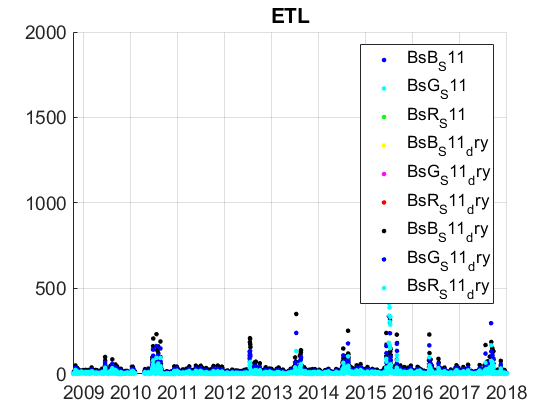

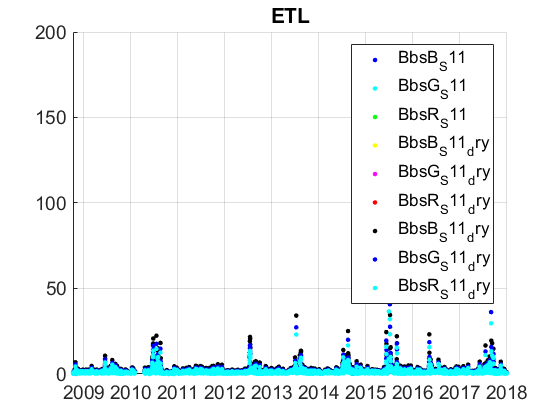

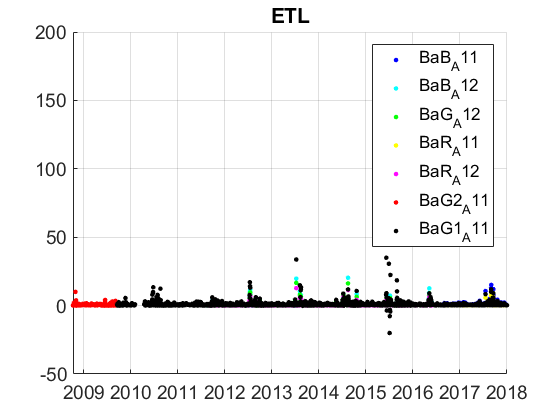

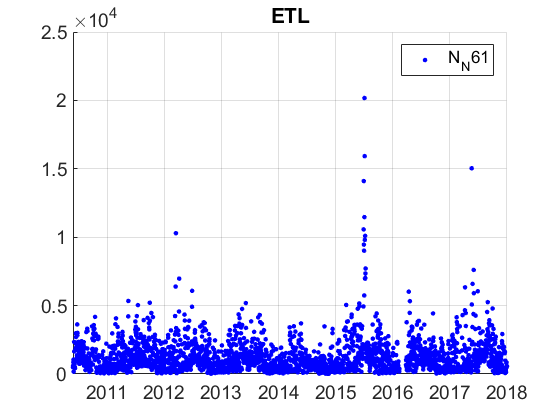

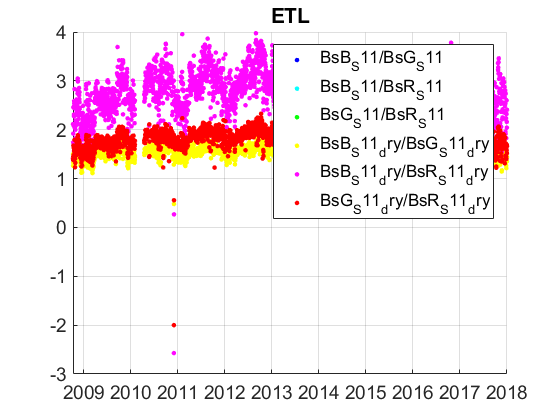

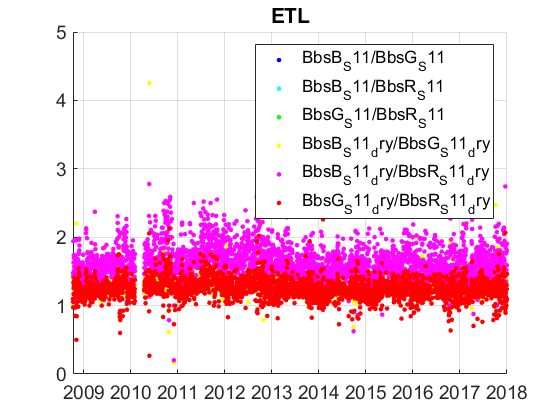

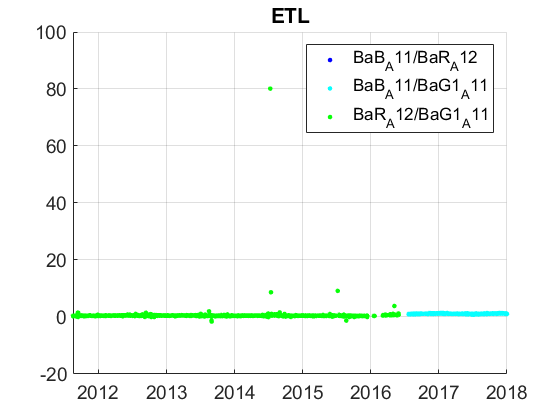

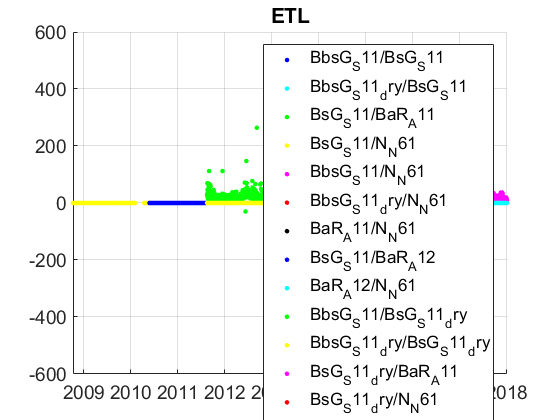


plotFigControl(ETL_rd,ETL_st.name);

% 1 size cut, ok
% sc: ok, no negatives, clear seasonal cycle max in summer
% RH > 50% only in summer, not all data

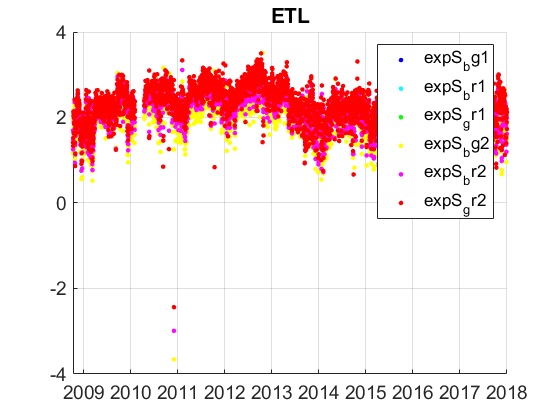

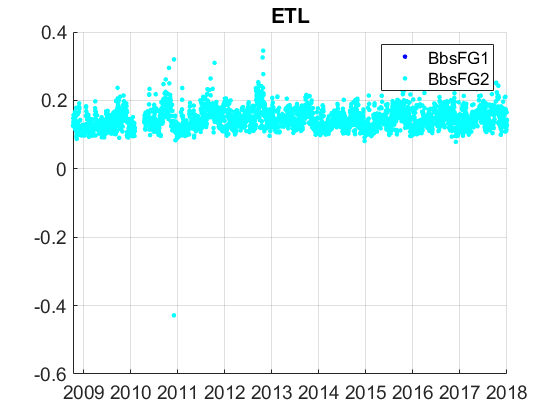

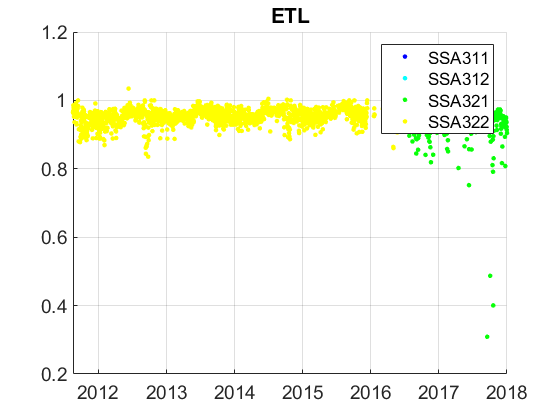

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
ETL_cal=compute_exp_SSA(ETL_rd,lambdaSC, lambdaAE);
plotFigControl_cal(ETL_cal, ETL_st.name);

hold on;
plot(ETL_cal.Time, ETL_rd.BaB_A11./ETL_rd.BaR_A11,'.');
plot(ETL_cal.Time, ETL_rd.BaB_A11./ETL_rd.BaG1_A11,'.');
plot(ETL_cal.Time, ETL_rd.BaB_A12./ETL_rd.BaR_A12,'.');
plot(ETL_cal.Time, ETL_rd.BaB_A12./ETL_rd.BaG1_A11,'.');

%Questions:
%problems:

%Humidity (U): the maxima is clearly decreasing. Did you change the drying procedure ?
%scat: there is some very high values in July 2015. What happened? Should be delete them?
%scat: clear modification of the wavelength dependence (exponent) approximately in May 2013: can you explain it ?

%abs: Betsy send me what she found in EBAS. I don't understand the instrumental change:
% there is one 1w serie from end 2008 to September 2009
% another 3w time series from August 2011 to June 2016
%another 2w (blue and red) series since July 2016
% and another (probably constructed by Betsy, in blakc on a figure) one from September 2009 to end 2017

%abs: from the ratio, it seems that the  time series BaB/BaR from A11 to A12 areok, but that the BaG1 is strange

%abs: very high values in July 2015 to delete ?

%N also has high values in July 2015 (N only from mid 2010)



ETL_t=timetable(ETL_rd.Time);
% begin at the beginning of a year: 2009
%end: 2017 --> 9 years

%U_S11: no data to delete
%U2: on the first one y (approximately<)
% do one time series with U2 and U1
%ATTENTION: the program uses the wrong U to calculate the dry data: do it rigth

%sc exponent: very low values 4 december 2010 to delete

%abs: extremes negatives and in July 2015 to delete 
%abs exp to compute, but only available from august 2011 (not enough for trend)